# LB3: Verification of Functionality of Buck Converter

Kristtiya Guerra and Aydin O'Leary

clear;

Import Data

Both_4V =readtable('4VData.csv');
Both_6V =readtable('6VData.csv');
Both_8V =readtable('8VData.csv');
Max = readtable('959VData.csv');
Vg = 18; %Volts in

#### Plot Shunt resistor Vout at 4V

% time_Shunt = table2array(Shunt_4V(:,1));
% Vout_Shunt = table2array(Shunt_4V(:,2));
% 
% figure(1)
% plot(time_Shunt,Vout_Shunt) %Plot Vout of Shunt resistor
% hold on
% xlabel('Time (ms)')
% ylabel('Voltage (V)')
% title('Voltage at shunt resistor, V_{shunt}, when V_{out}=4V')
% hold off

#### Analysis for 4V output of Buck converter

Calculating Current across Shunt Resistor

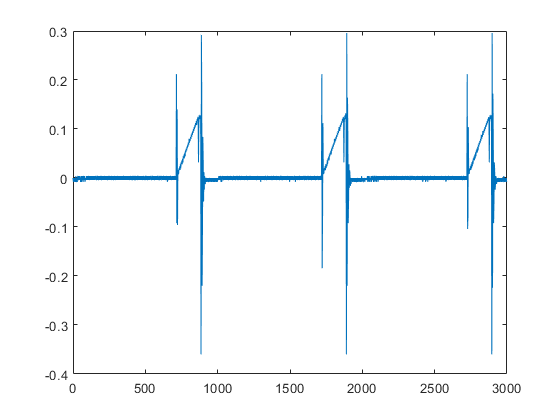

time_4V = (5*10^-8) .* (table2array(Both_4V(:,1)));

Vout_drain4 = table2array(Both_4V(:,2)); %Voltage of Drain
Vout_Shunt4 = table2array(Both_4V(:,3)); %Voltage of Shunt Resistor of 0.05 Ohms
Iout_Shunt4 = Vout_Shunt4./0.05;         %Current Across Shunt

plot(time_4V/(2*10^-8),Vout_Shunt4,'-') %Plot Vout of Shunt resistor

Calculating Inductance

delta_Iout_4 = (Iout_Shunt4(342)-Iout_Shunt4(300))/(time_4V(342)-time_4V(300))

delta_Iout_4 = 8.0000e+05

Inductance1= mean((Vg -4)*(1/delta_Iout_4))

Inductance1 = 1.7500e-05


% Peak 2
delta_Iout_4 = (Iout_Shunt4(745)-Iout_Shunt4(700))/(time_4V(745)-time_4V(700))

delta_Iout_4 = 7.4667e+05

Inductance1b= mean((Vg -4)*(1/delta_Iout_4))

Inductance1b = 1.8750e-05


% Peak 3
delta_Iout_4 = (Iout_Shunt4(1140)-Iout_Shunt4(1100))/(time_4V(1140)-time_4V(1100))

delta_Iout_4 = 8.0000e+05

Inductance1c= mean((Vg -4)*(1/delta_Iout_4))

Inductance1c = 1.7500e-05


% Average
MeanInd1 = (Inductance1+Inductance1b+Inductance1c)/3

MeanInd1 = 1.7917e-05

#### Analysis for 6V output of Buck converter

Calculating Current across Shunt Resistor

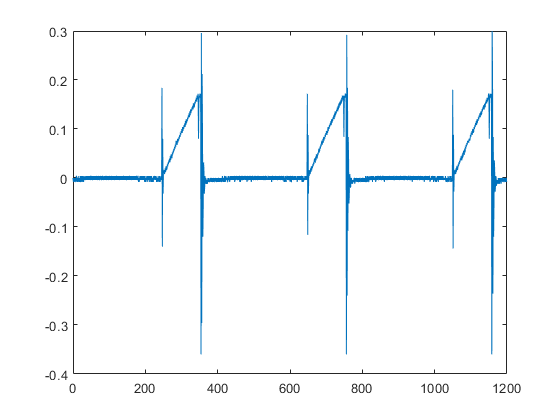

time_6V = 5*10^(-8) *table2array(Both_6V(:,1));
Vout = 6.045;%Voltage out of converter
Vout_drain6 = table2array(Both_6V(:,2));
Vout_Shunt6 = table2array(Both_6V(:,3));
Iout_Shunt6 = Vout_Shunt6./0.05;

plot(time_6V/(5*10^-8),Vout_Shunt6,'-') %Plot Vout of Shunt resistor

Calculating Inductance

%Peak 1
delta_Iout_6 = (Iout_Shunt6(340)-Iout_Shunt6(260))/(time_6V(340)-time_6V(260))

delta_Iout_6 = 7.2000e+05

Inductance2= mean((Vg - Vout)*(1/delta_Iout_6))

Inductance2 = 1.6604e-05

%Peak 2
delta_Iout_6 = (Iout_Shunt6(740)-Iout_Shunt6(660))/(time_6V(740)-time_6V(660))

delta_Iout_6 = 6.2000e+05

Inductance2b= mean((Vg - Vout)*(1/delta_Iout_6))

Inductance2b = 1.9282e-05

%peak 3
delta_Iout_6 = (Iout_Shunt6(1140)-Iout_Shunt6(1080))/(time_6V(1140)-time_6V(1080))

delta_Iout_6 = 6.6667e+05

Inductance2c= mean((Vg - Vout)*(1/delta_Iout_6))

Inductance2c = 1.7932e-05

%average
MeanInd2 = (Inductance2+Inductance2b+Inductance2c)/3

MeanInd2 = 1.7940e-05

#### Plot Voltages when Vout at 8V

time_8V = (5*10^-8)*table2array(Both_8V(:,1));
Vout = 8.07; %Voltage out of converter
Vout_drain8 = table2array(Both_8V(:,2));
Vout_Shunt8 = table2array(Both_8V(:,3));
Iout_Shunt8 = Vout_Shunt8./0.05;

Calculating Inductance

%peak 1
delta_Iout_8 = (Iout_Shunt8(340)-Iout_Shunt8(220))./(time_8V(340)-time_8V(220))

delta_Iout_8 = 5.2000e+05

Inductance3= mean((Vg - Vout)*(1/delta_Iout_8))

Inductance3 = 1.9096e-05

%Peak 2
delta_Iout_8 = (Iout_Shunt8(740)-Iout_Shunt8(640))./(time_8V(740)-time_8V(640))

delta_Iout_8 = 544000

Inductance3b= mean((Vg - Vout)*(1/delta_Iout_8))

Inductance3b = 1.8254e-05

%Peak 3
delta_Iout_8 = (Iout_Shunt8(1140)-Iout_Shunt8(1020))./(time_8V(1140)-time_8V(1020))

delta_Iout_8 = 5.4667e+05

Inductance3c= mean((Vg - Vout)*(1/delta_Iout_8))

Inductance3c = 1.8165e-05


Avg_ind3 = (Inductance3 + Inductance3b + Inductance3c)/3

Avg_ind3 = 1.8505e-05

#### Plot Voltages when Vout at 10V

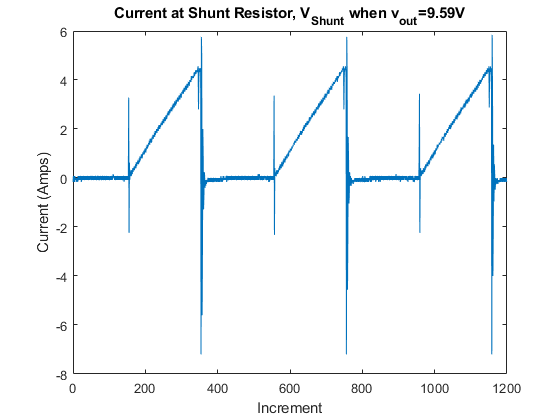

time_10V = (5*10^(-8))*table2array(Max(:,1));
Vout = 9.59; %Voltage out of converter
Vout_drain10 = table2array(Max(:,2));
Vout_Shunt10 = table2array(Max(:,3));
Iout_Shunt10 = Vout_Shunt10./0.05;

plot(time_10V/(5*10^-8),Iout_Shunt10,'-') %Plot Vout of Shunt resistor
hold on
xlabel('Increment')
ylabel('Current (Amps)')
title('Current at Shunt Resistor, V_{Shunt} when v_{out}=9.59V');
hold off

Calculating Inductance

delta_Iout_10 = (Iout_Shunt10(340)-Iout_Shunt10(180))./(time_10V(340)-time_10V(180))

delta_Iout_10 = 460000

Inductance4= mean((Vg - Vout)*(1/delta_Iout_10))

Inductance4 = 1.8283e-05


delta_Iout_10 = (Iout_Shunt10(720)-Iout_Shunt10(600))./(time_10V(720)-time_10V(600))

delta_Iout_10 = 4.4000e+05

Inductance4b= mean((Vg - Vout)*(1/delta_Iout_10))

Inductance4b = 1.9114e-05


delta_Iout_10 = (Iout_Shunt10(1140)-Iout_Shunt10(1000))./(time_10V(1140)-time_10V(1000))

delta_Iout_10 = 4.5714e+05

Inductance4c= mean((Vg - Vout)*(1/delta_Iout_10))

Inductance4c = 1.8397e-05


Avg_ind4 = (Inductance4 + Inductance4b + Inductance4c)/3

Avg_ind4 = 1.8598e-05

Mean Inductance

OverallInductance= (Avg_ind4+Avg_ind3+MeanInd2+MeanInd1)/4

OverallInductance = 1.8240e-05

#### Plot All Vdrain vs Vshunt

4V output

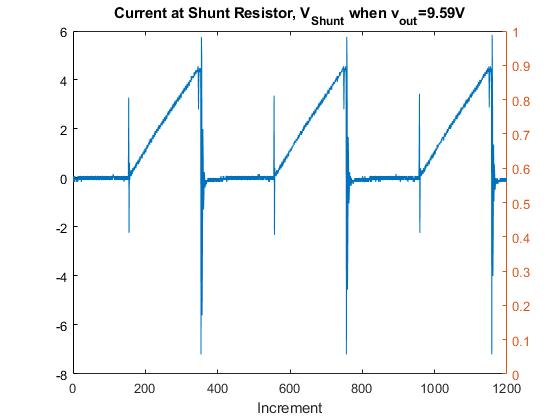

figure(1)
yyaxis left
plot(time_4V,Vout_Shunt4) %Plot Vout of Shunt resistor

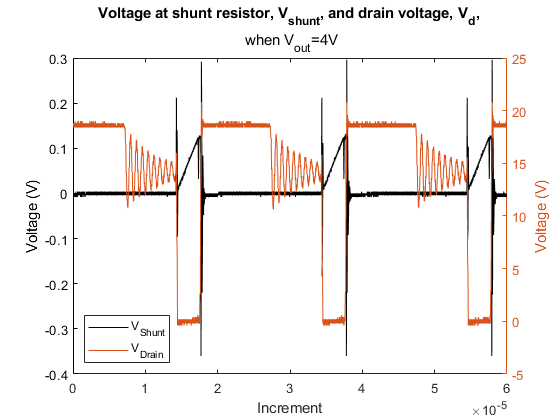

ylabel('Voltage (V)')
yyaxis right
plot(time_4V,Vout_drain4) %Plot Vout of Shunt resistor
legend({'V_{Shunt}','V_{Drain}'},'Location','southwest');
title('Voltage at shunt resistor, V_{shunt}, and drain voltage, V_{d},',' when V_{out}=4V')
ylabel('Voltage (V)');

6V Output

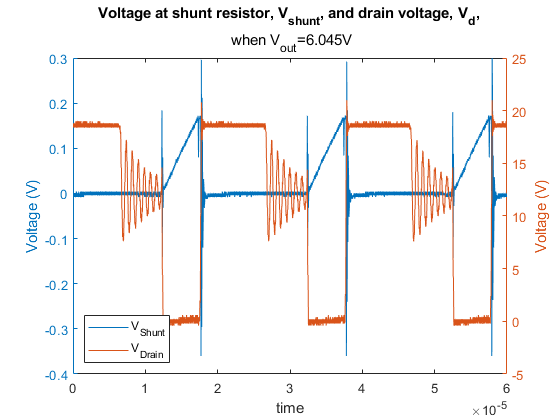

figure(3)
yyaxis left
plot(time_6V,Vout_Shunt6) %Plot Vout of Shunt resistor
ylabel('Voltage (V)')
yyaxis right
plot(time_6V,Vout_drain6) %Plot Vout of Shunt resistor
ylabel('Voltage (V)');
title('Voltage at shunt resistor, V_{shunt}, and drain voltage, V_{d},',' when V_{out}=6.045V')
xlabel('time')
legend({'V_{Shunt}','V_{Drain}'},'Location','southwest');

8V Ouput

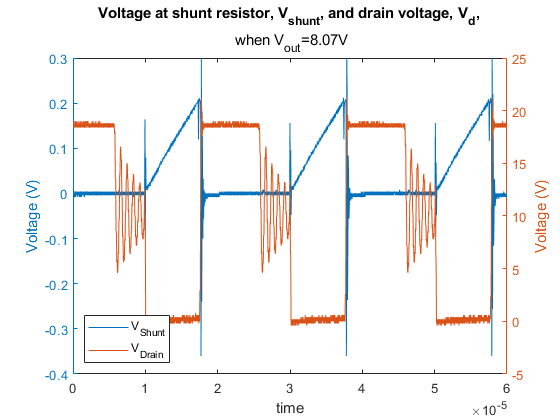

figure(4)
xlabel('time')
yyaxis left
plot(time_8V,Vout_Shunt8,'-') %Plot Vout of Shunt resistor
ylabel('Voltage (V)')
yyaxis right
plot(time_8V,Vout_drain8,'-') %Plot Vout of Shunt resistor
ylabel('Voltage (V)');
title('Voltage at shunt resistor, V_{shunt}, and drain voltage, V_{d},',' when V_{out}=8.07V')
legend({'V_{Shunt}','V_{Drain}'},'Location','southwest');

9.59V Output

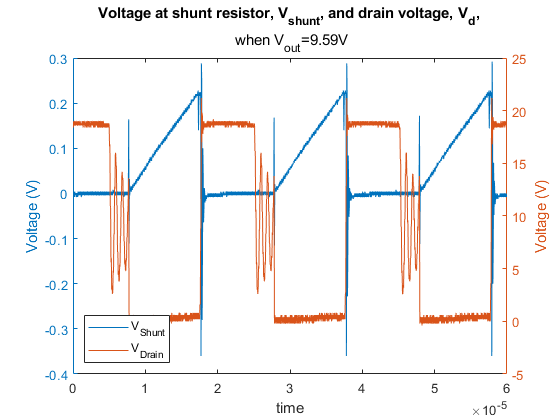

figure(5)
xlabel('time')
yyaxis left
plot(time_10V,Vout_Shunt10,'-') %Plot Vout of Shunt resistor
ylabel('Voltage (V)')
yyaxis right
plot(time_10V,Vout_drain10,'-') %Plot Vout of Shunt resistor
ylabel('Voltage (V)');
title('Voltage at shunt resistor, V_{shunt}, and drain voltage, V_{d},',' when V_{out}=9.59V')
legend({'V_{Shunt}','V_{Drain}'},'Location','southwest');